# Question 7.1

Load the signal vinyl1.wav in Matlab with audioread and listen if you can hear cracks and a loud click (use the function sound). 

Then plot the vinyl signal. 

Select a crack and remove it by hand. 

Plot the result and save the new signal with audiowrite. 

Listen again to the vinyl signal in the media player.

clear
[y,Fs]=audioread('vinyl1.wav')

y =     0.0009
    0.0008
    0.0009
    0.0010
    0.0012
    0.0011
    0.0009
    0.0009
    0.0009
    0.0005


Fs = 44000

% your code here
%sound(y, Fs)


n = 1:length(y)

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = (n-1)/Fs %time vector

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


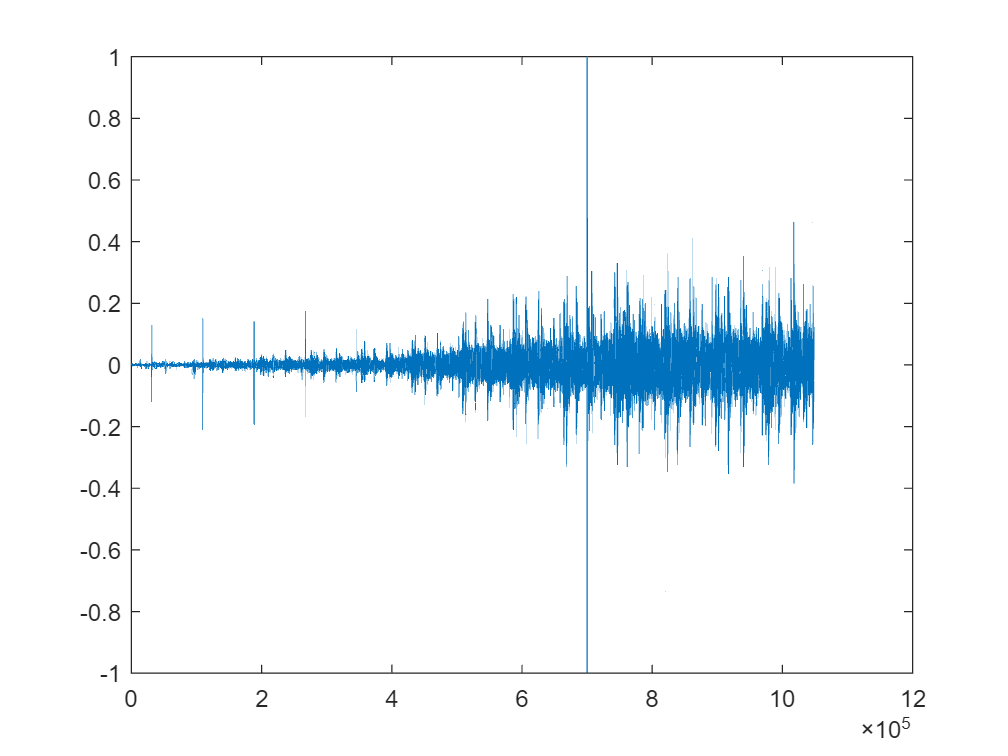

%plot signal to know which part should we remove 
figure
plot(y)

% title('vinyl1 original')
%remove cracks --> check x of crakcs and set amplitude to 0 
% --> DOESNT WORK???

%%NEEDED TO ASK FOR SOME HELP BECAUSE WTFFFFF

%crack to remove 
c1 = 109817-100

c1 = 109717

c2 = c1+200

c2 = 109917

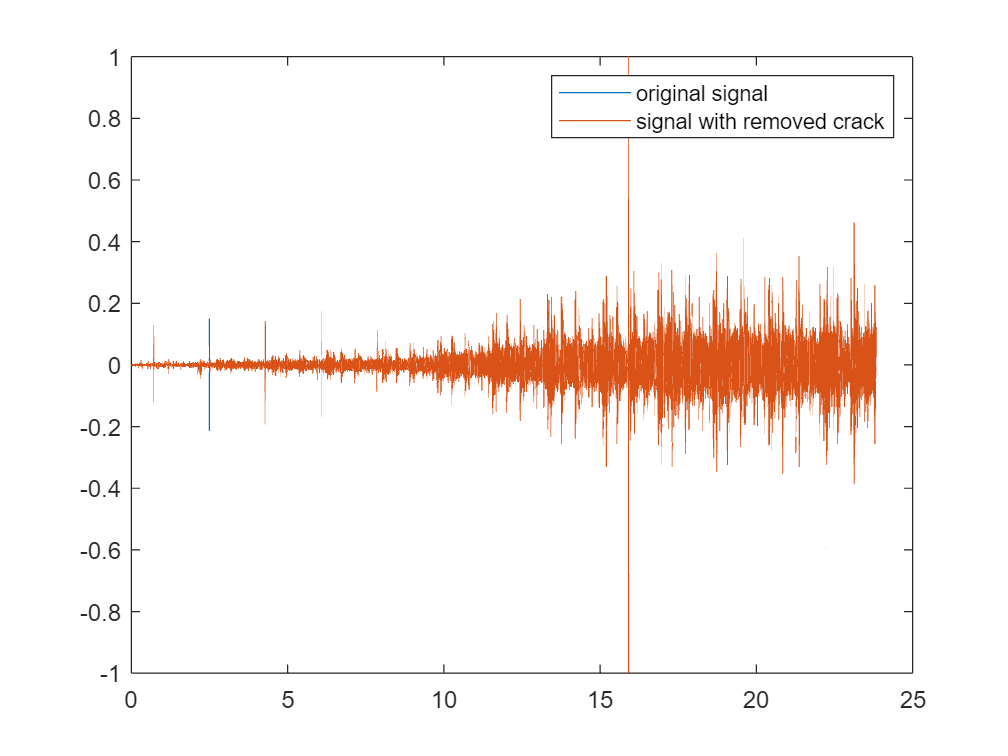

yNoCracks = denoisefromcracks(y,c1,c2);
yNoCracks(c1:c2);

%plot everything
figure
plot(t, y, 'DisplayName','original signal')
hold on
plot(t, yNoCracks, 'DisplayName', 'signal with removed crack')
hold off
legend('-DynamicLegend')

%repeat until no cracks left
%build array with all cracks:
cracks =[31116, 109817, 188480, 267157,700100]

cracks =        31116      109817      188480      267157      700100


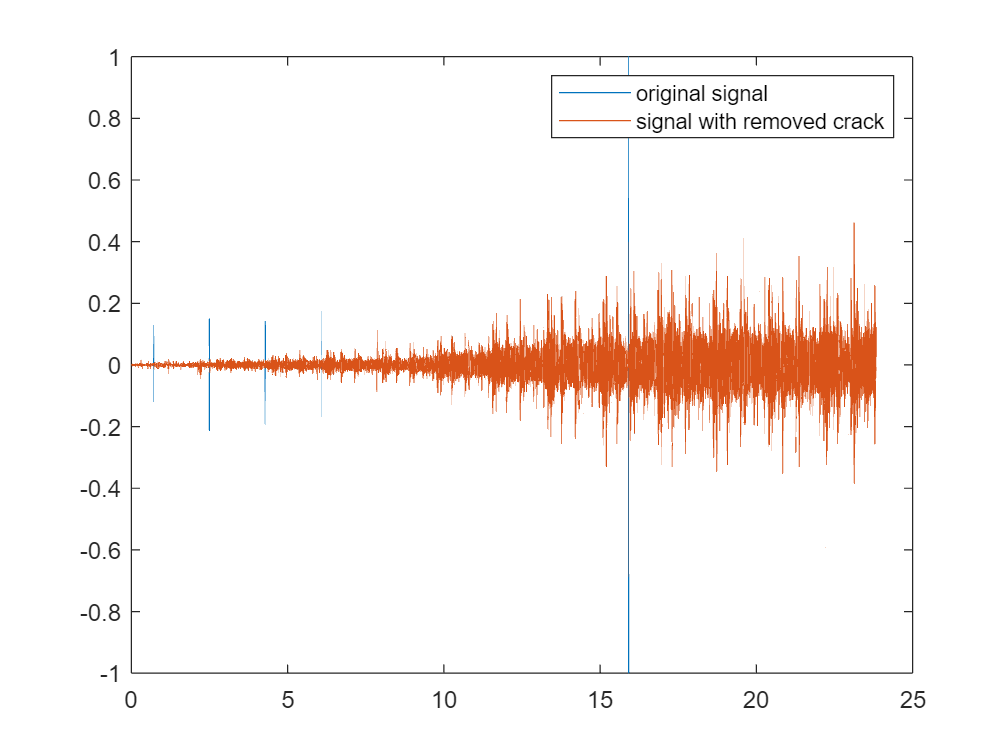

for i = 1:length(cracks)
    c1 = cracks(i) - 150;
    c2 = c1 + 250;

    % Ensure indices are within bounds
    c1 = max(c1, 1);
    c2 = min(c2, length(y));

    % Remove the crack using your denoising function
    yNoCracks = denoisefromcracks(yNoCracks, c1, c2);
end

%plot everything
figure
plot(t, y, 'DisplayName','original signal')
hold on
plot(t, yNoCracks, 'DisplayName', 'signal with removed crack')
legend('-DynamicLegend')


%save new signal
audiowrite("vinyl1cleaned.wav",yNoCracks,Fs)
% sound(yNoCracks,Fs)


## Question 7.2

Load again the original vinyl signal and apply mean filtering as you have learned in Practical Assignment 3. 

Try a few different filter lengths, for example 10, 100 and 1000. 

Save the filtered signals and listen to the result

clear; close all

[y,Fs]=audioread('vinyl1.wav');
% your code here
n = 1:length(y)

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = (n-1)/Fs %time vector

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


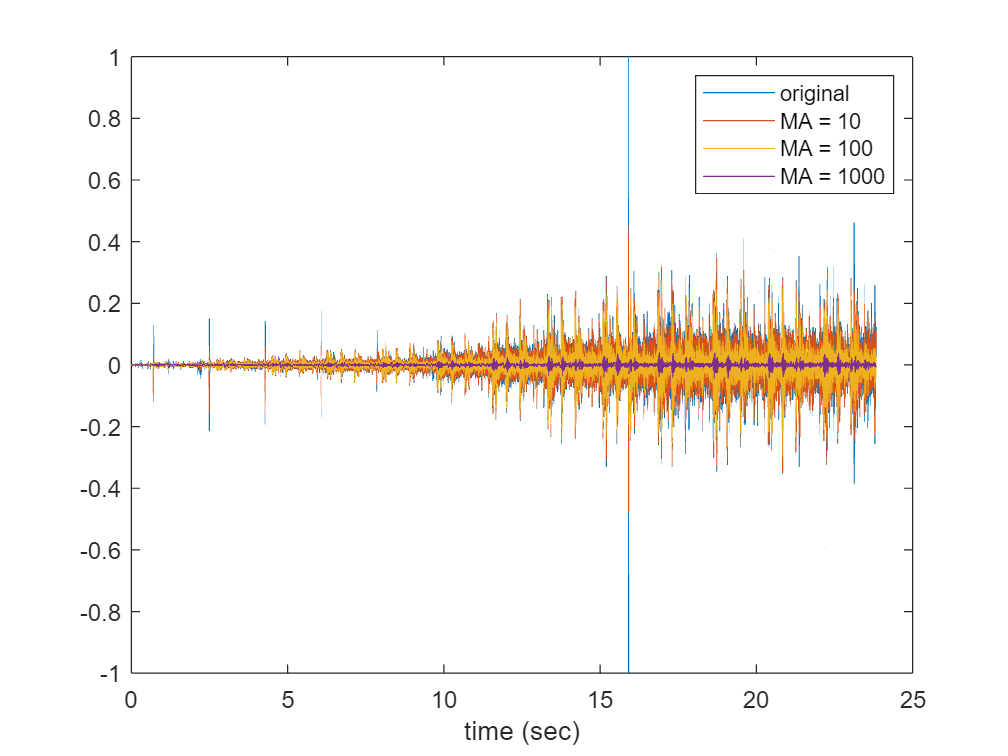


%%copy - paste - modify to fit from lab3

y10 = movingAVGfilter(y,10);
y100 = movingAVGfilter(y,100);
y1000 = movingAVGfilter(y, 1000);

% plot all MovAvg filter and the original signal
figure
plot(t,y)
hold on

plot(t,y10)
plot(t,y100)
plot(t,y1000)
hold off

legend('original', 'MA = 10','MA = 100','MA = 1000')
xlabel('time (sec)')

%save filtered signal and listen
audiowrite("vinyl1cleanedMA10.wav",y10,Fs)
% sound(y10,Fs)

audiowrite("vinyl1cleanedMA100.wav",y100,Fs)
% sound(y100,Fs)

audiowrite("vinyl1cleanedMA1000.wav",y1000,Fs)
% sound(y1000,Fs)



## Question 7.3

Load cd1.wav into Matlab and listen to it. Denoise the signal by wavelet shrinkage with soft thresholding. 

Use a 3 level decomposition with the Daubechies wavelet of filter length 6.

Use Visushrink as described in the book and told in the lectures. 

Save your denoised signal as cd3.wav.

**Hint:** Apply formula 9.4 (page 321) on all your detail coefficients. Lambda can be obtained using equation 9.9. And sigma of 9.9 can be estimated applying equation 9.10 on your first detail coefficients. 

Formula: 

clear
[y3,Fs]=audioread('cd1.wav');
y3

y3 =     0.0111
   -0.0164
   -0.0439
    0.0151
    0.0558
   -0.0130
    0.0308
   -0.0120
   -0.0524
    0.0142


% your code here 
% sound(y, Fs)

n = 1:length(y3)

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = (n-1)/Fs %time vector

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


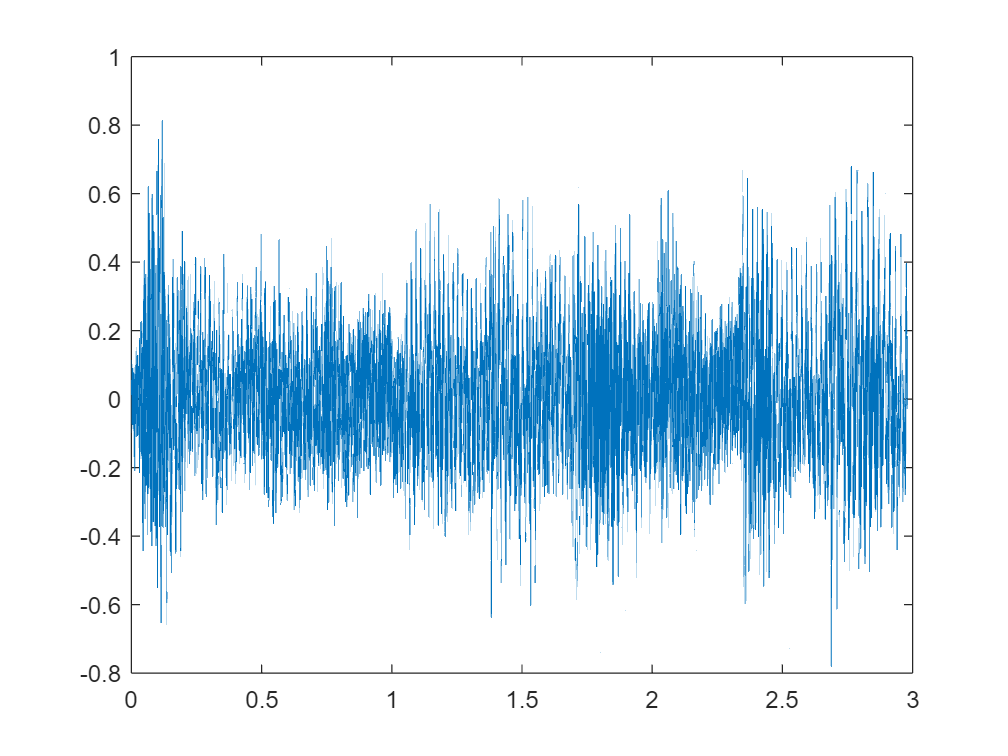

%plot  
figure
plot(t, y3)

**This was done to test but not used later**

%Use a 3 level decomposition with the Daubechies wavelet of filter length 6.
%%from lab6
[f_3,g_3]=computeDBwavelet(3) %filter of length 6

f_3 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352
    0.0352   -0.0854   -0.1350    0.4599    0.8069    0.3327


g_3 =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327
    0.3327   -0.8069    0.4599    0.1350   -0.0854   -0.0352


Lp=f_3(1,:)

Lp =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352


Hp=g_3(1,:)

Hp =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327


C = wldecom(y3,3,Lp,Hp)

C =    -0.0432   -0.0631    0.0403    0.0199    0.1900   -0.0683    0.1012   -0.0058   -0.0405   -0.0772   -0.0424   -0.1042   -0.0782   -0.0701    0.0169    0.0872    0.1095    0.0384    0.0726    0.0557   -0.0465   -0.0580    0.1012    0.0768   -0.0953   -0.0789    0.0856   -0.0578   -0.0750   -0.1668   -0.1419   -0.1126    0.0345   -0.0580   -0.0509   -0.0413    0.0253    0.0191   -0.0221   -0.0205    0.0031   -0.1636   -0.0794    0.0369   -0.0991   -0.0993    0.0491   -0.0175    0.0921    0.0305


**end**

**This is where the magic happened (check visushrink)**

[denoisedC, MAD, estvariance, lambda]=visushrink(y3, 3) 

denoisedC =    -0.0432   -0.0631    0.0403    0.0199    0.1900   -0.0683    0.1012   -0.0058   -0.0405   -0.0772   -0.0424   -0.1042   -0.0782   -0.0701    0.0169    0.0872    0.1095    0.0384    0.0726    0.0557   -0.0465   -0.0580    0.1012    0.0768   -0.0953   -0.0789    0.0856   -0.0578   -0.0750   -0.1668   -0.1419   -0.1126    0.0345   -0.0580   -0.0509   -0.0413    0.0253    0.0191   -0.0221   -0.0205    0.0031   -0.1636   -0.0794    0.0369   -0.0991   -0.0993    0.0491   -0.0175    0.0921    0.0305


MAD = 0.0179

estvariance = 0.0266

lambda = 0.1282

% Use Visushrink as described in the book and told in the lectures.
%WTFFFFFFF??? okay now!!!

%should be different
check= isequal(C, denoisedC)

check = logical
   0


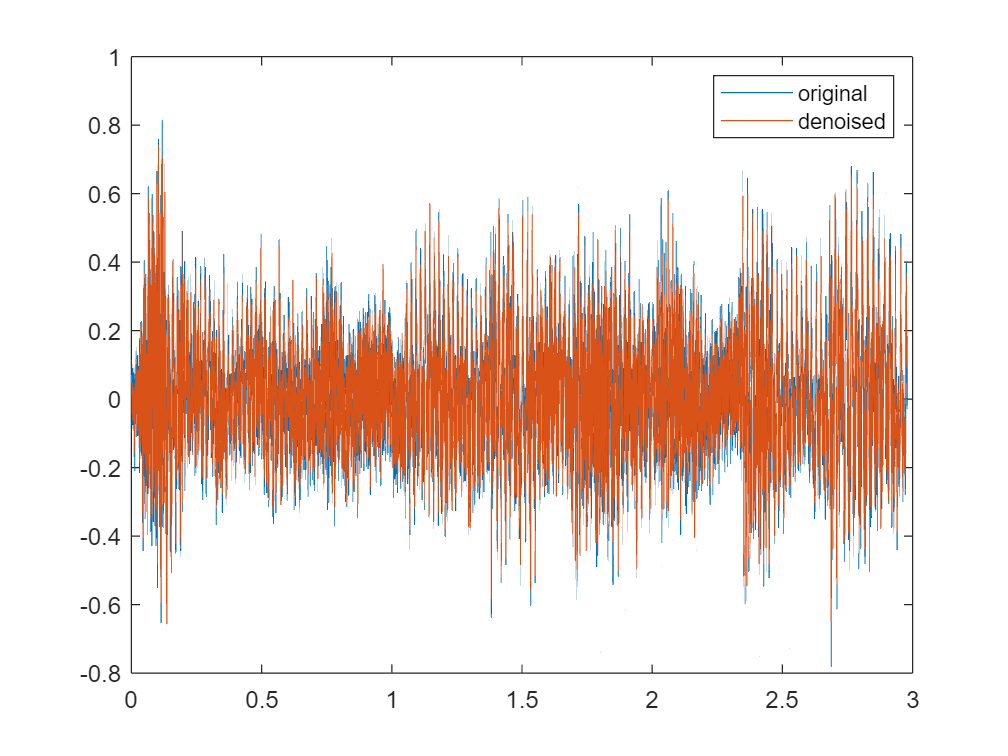

%reconstruct the signal now that it is denoised
denoised_y = wlrecon(denoisedC,3,Lp,Hp);

figure
plot(t,y3, 'DisplayName', 'original')
hold on
plot(t, denoised_y, 'DisplayName', 'denoised')
hold off
legend("original","denoised")

%why is it not plotting???

%Save your denoised signal as cd3.wav.
audiowrite("cd3.wav", denoised_y, Fs)


## Question 7.4

cd2.wav is the clean version of cd1.wav. 

Determine the SNR (signal-to-noise ratio) in decibels of cd1.wav. 

Use the following formula: SNR = 10 log10 PL i=1 x[i] 2 PL i=1 e[i] 2 where e[i] is the error signal between the noisy signal z[n] and the clean signal x[i]. So e[i] = |x[i] − z[i]|. L is the length of the signals x[n], z[n] and e[n].

 Determine also the SNR of your cd3.wav. How much did your SNR improved/deteriorated after wavelet denoising? 

[yor,Fs]=audioread('cd2.wav');
% Your code here
%e(i) = x(i)-z(i),x is cleanded signa, z is noisy signal
x=yor(:)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z = y3(:) %from previous question

z =     0.0111
   -0.0164
   -0.0439
    0.0151
    0.0558
   -0.0130
    0.0308
   -0.0120
   -0.0524
    0.0142



e=x-z

e =    -0.0111
    0.0164
    0.0439
   -0.0151
   -0.0558
    0.0130
   -0.0308
    0.0120
    0.0524
   -0.0142




SNR12= 10*log10(sum(x.^2)/sum(e.^2))

SNR12 = 7.4188

%now repeat with cd3 when i have it 

[z3,~]=audioread('cd3.wav');
e3 = x-z3

e3 =    -0.0708
   -0.0487
   -0.0300
   -0.0110
    0.0033
    0.0066
    0.0096
    0.0129
    0.0157
    0.0173


SNR32= 10*log10(sum(x.^2)/sum(e3.^2))

SNR32 = 8.0310

%then compute difference between SNR12 and SNR32
diff = abs(SNR12-SNR32)

diff = 0.6123

## Question 7.5

Take in essence the decomposition from exercise 4 of the lab on Daubechies wavelets, but add white Gaussian noise with a standard deviation of 25 to the image before decomposing it. (note that in theory you could get negative values and it will depend on how you plot it, whether you need to do something extra to avoid this or what the effect will be). 

Perform wavelet shrinkage on that image and reconstruct it. At each level B is considered low-pass output and V, H and D are considered high-pass output. 

clear all; close all; clc
load lab5_dataset3.mat
% Your code here

% %%STABILIZE THE RESULTS FROM USING A RANDOM FUNCTION
% rng(123);  
%  add white Gaussian noise with a standard deviation of 25 to the image 
wgn_im = s + 25 * randn(size(s));

%this is a copy paste of ex4 in lab 6
Lp=[0.4830    0.8365    0.2241   -0.1294];
Hp=fliplr(Lp).*[-1 1 -1 1];


%  Plot the results
figure
subplot(1,3,1);
image(wgn_im)
colormap gray
axis square
axis off
title('original');

%Decompose following the same logic as in Lab4-Haar
[B1,H1,V1,D1] = wldecom_2(wgn_im,Lp, Hp);
[B2,H2,V2,D2]=wldecom_2(B1,Lp,Hp); %go to level2 wavelets but with approximation coefs (B) from level 1
%combine back approximation and detail coefficients together
lvl2=[B2 V2;H2 D2];
lvl1=[lvl2 V1;H1 D1];

% Plot the wavelet transform of the noisy image
subplot(1,3,2);
imagesc(lvl1)
colormap gray
axis square
title('wavelet transform (noisy)');

% Apply wavelet shrinkage to the coefficients for the second level
[denoisedC2, MAD2, estvar2, lambda2] = visushrink2d(B2, H2, V2, D2, 2, Lp, Hp)

denoisedC2 = struct with fields:
    B: [64×64 double]
    H: [64×64 double]
    V: [64×64 double]
    D: [64×64 double]


MAD2 = 19.5729

estvar2 = 29.0184

lambda2 = 125.9305


% Extract individual denoised coefficients for the second level
B2_denoised = denoisedC2.B;
H2_denoised = denoisedC2.H;
V2_denoised = denoisedC2.V;
D2_denoised = denoisedC2.D;

% Apply wavelet shrinkage to the coefficients for the first level
[denoisedC1, MAD1, estvar1, lambda1] = visushrink2d(B1, H1, V1, D1, 2, Lp, Hp)

denoisedC1 = struct with fields:
    B: [128×128 double]
    H: [128×128 double]
    V: [128×128 double]
    D: [128×128 double]


MAD1 = 17.0925

estvar1 = 25.3410

lambda1 = 117.7889

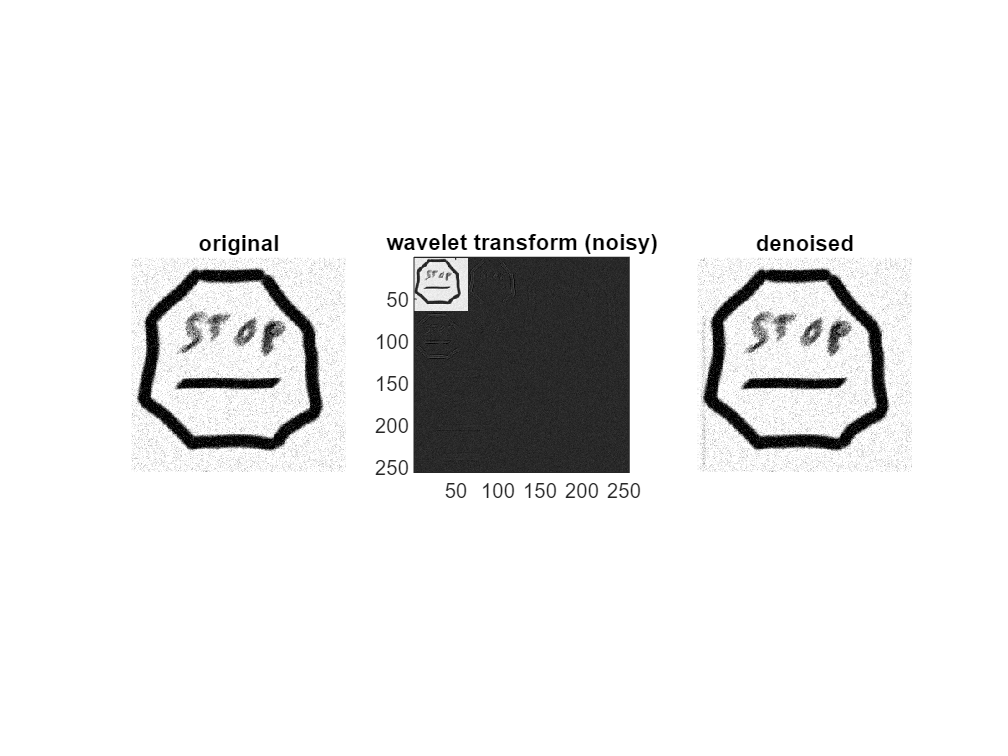


% Extract individual denoised coefficients for the second level
B1_denoised = denoisedC1.B;
H1_denoised = denoisedC1.H;
V1_denoised = denoisedC1.V;
D1_denoised = denoisedC1.D;

% Reconstruct the denoised image for the second level
recon2 = wlrecon_2(B2_denoised, H2_denoised, V2_denoised, D2_denoised, Lp, Hp);

% Reconstruct the denoised image for the first level
recon1 = wlrecon_2(recon2, H1_denoised, V1_denoised, D1_denoised, Lp, Hp);

% Plot the denoised image
subplot(1,3,3);
image(recon1)
colormap gray
axis square
axis off
title('denoised');

%%NOT SURE IT ACTUALLY WORKED BUT YEAH...